clear all
load TR4_data.mat
S=[[5.7426e-3 4e-3 -2.4142e-3]',[9.0487e-3 5.5871e-3 2.7189e-3]'];

## movimento lineare

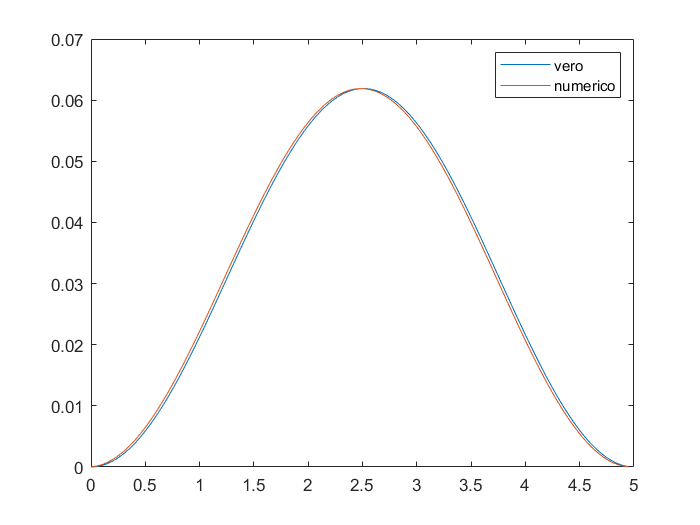

[Ql,Qpl,Qppl,Fql,Tl,Xl]=TR4_linearMov(S,@Cicloidale,5,link);
qp=diff(Ql(1,:,3))/(Tl(2)-Tl(1));
qpp=diff(Qpl(1,:,3))/(Tl(2)-Tl(1));
plot(Tl(1:end-1),Qpl(1,1:end-1,3),Tl(1:end-1),qp)
legend("vero","numerico")

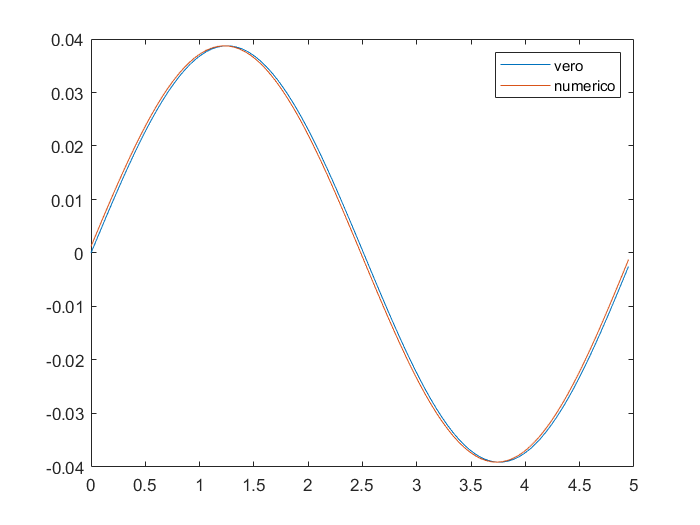

plot(Tl(1:end-1),Qppl(1,1:end-1,3),Tl(1:end-1),qpp)
legend("vero","numerico")

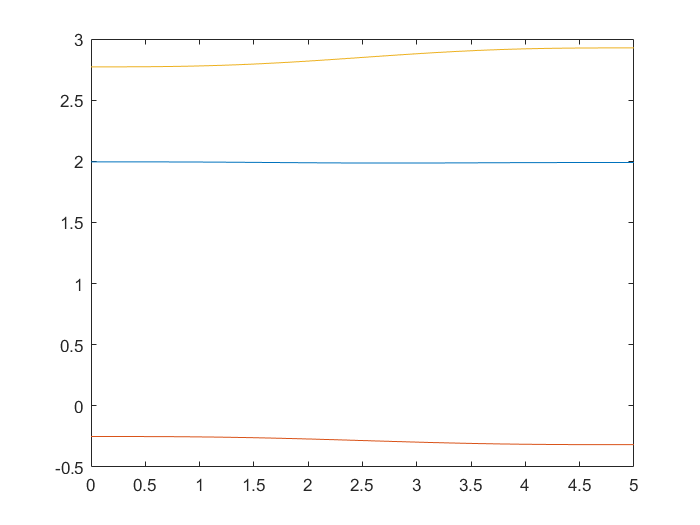

plot(Tl,Ql(1,:,1),Tl,Ql(1,:,2),Tl,Ql(1,:,3))

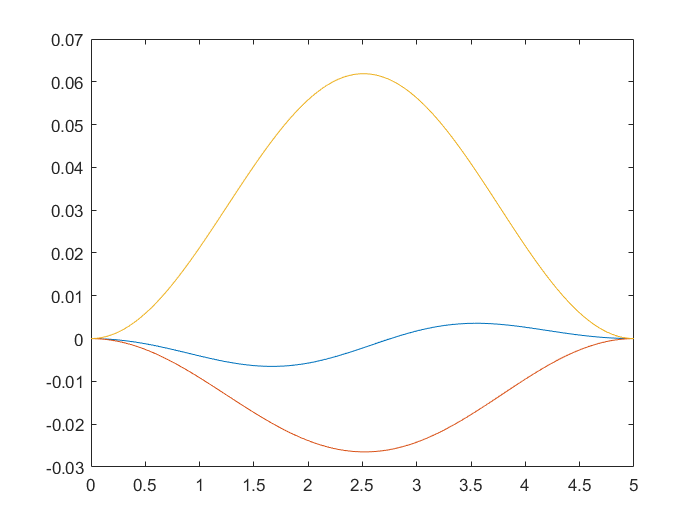

plot(Tl,Qpl(1,:,1),Tl,Qpl(1,:,2),Tl,Qpl(1,:,3))

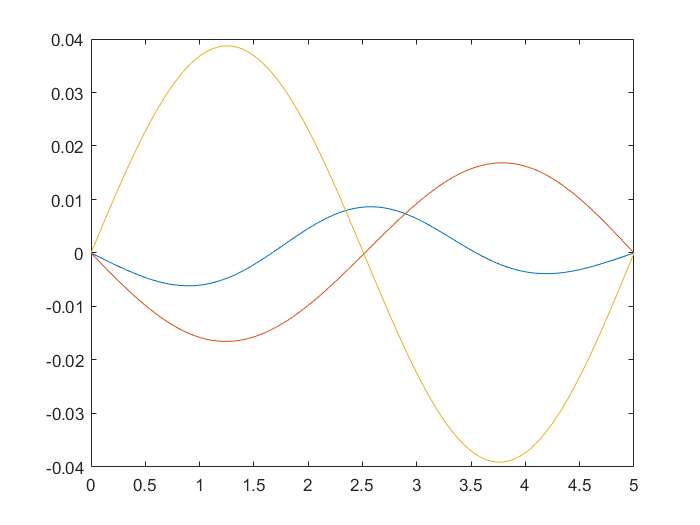

plot(Tl,Qppl(1,:,1),Tl,Qppl(1,:,2),Tl,Qppl(1,:,3))

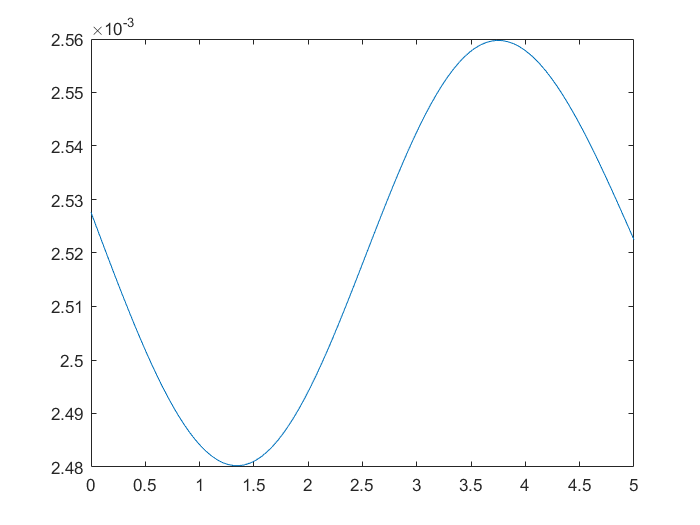

plot(Tl,Fql(1,:,1))

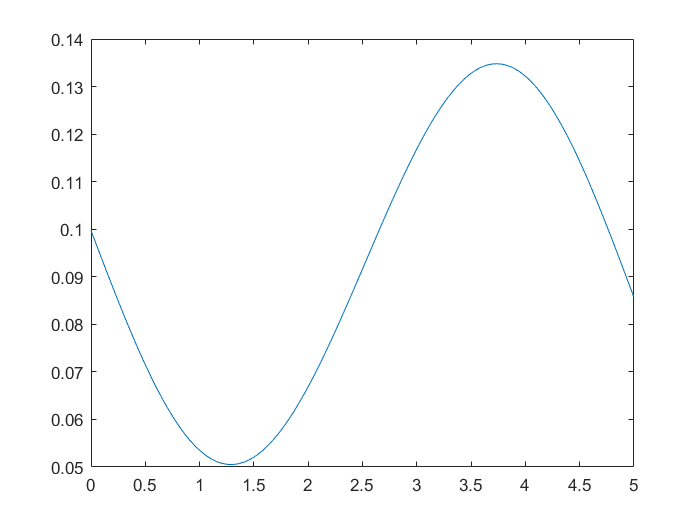

plot(Tl,Fql(1,:,2))

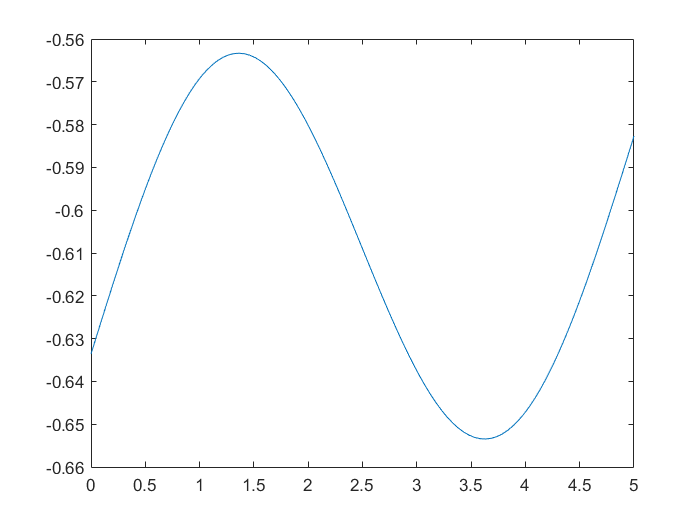

plot(Tl,Fql(1,:,3))

## movimento joint

Q1=TR4_invNumeric(S(:,1)',[0.5 0.5 0.5],link,1000);
Q2=TR4_invNumeric(S(:,2)',[0.5 0.5 0.5],link,1000);
Q=[Q1,Q2]

Q =     1.9953    1.9899
   -0.2507   -0.3173
    2.7723    2.9272


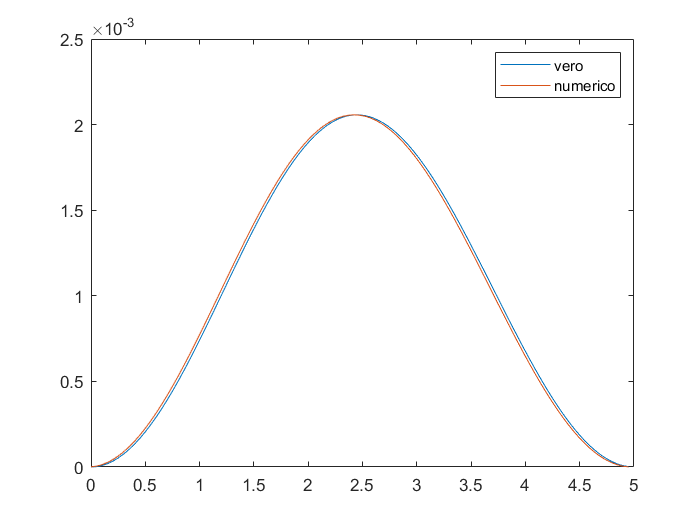

[X,Xp,Xpp,Fq,T,Q] = TR4_jointMov(Q,@Cicloidale,5,link);
xp=diff(X(1,:,3))/(T(2)-T(1));
plot(T(1:end-1),Xp(1,1:end-1,3),T(1:end-1),xp)
legend("vero","numerico")

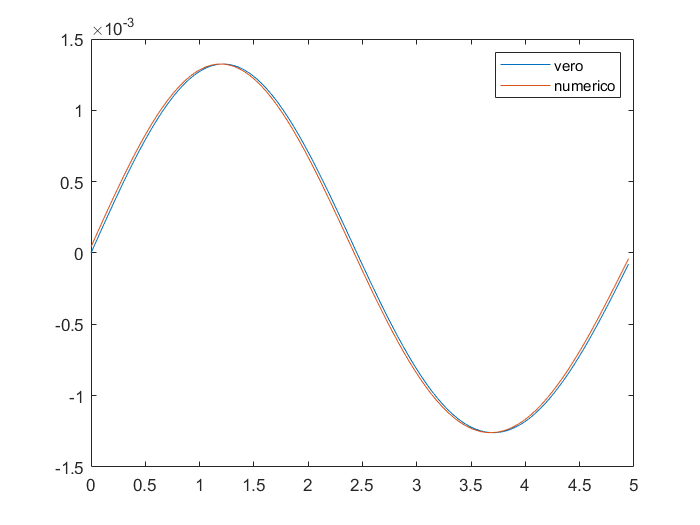

xpp=diff(Xp(1,:,3))/(T(2)-T(1));
plot(T(1:end-1),Xpp(1,1:end-1,3),T(1:end-1),xpp)
legend("vero","numerico")

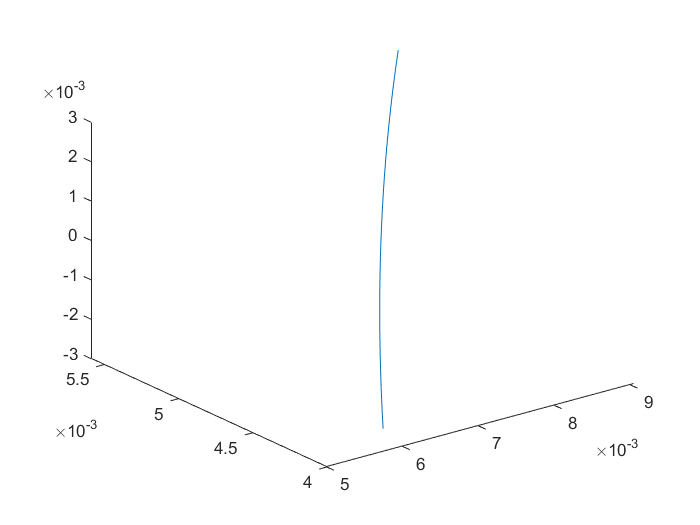

plot3(X(1,:,1),X(1,:,2),X(1,:,3))

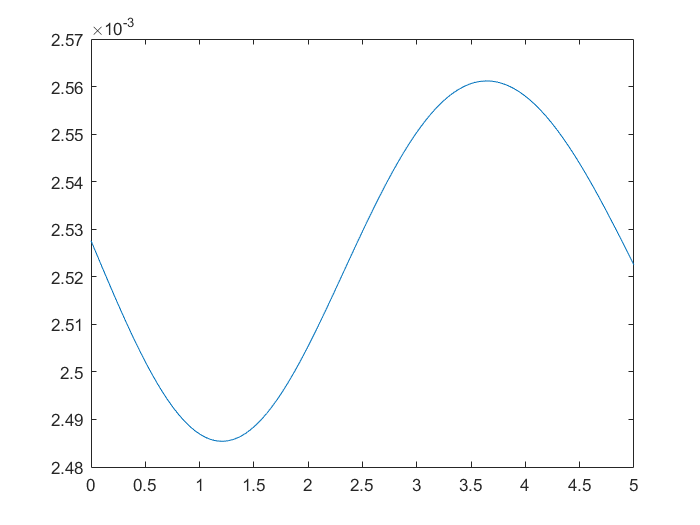

plot(T,Fq(1,:,1))

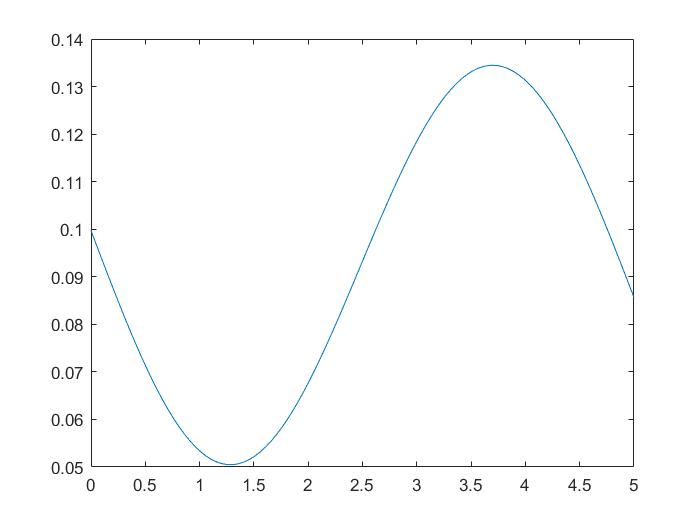

plot(T,Fq(1,:,2))

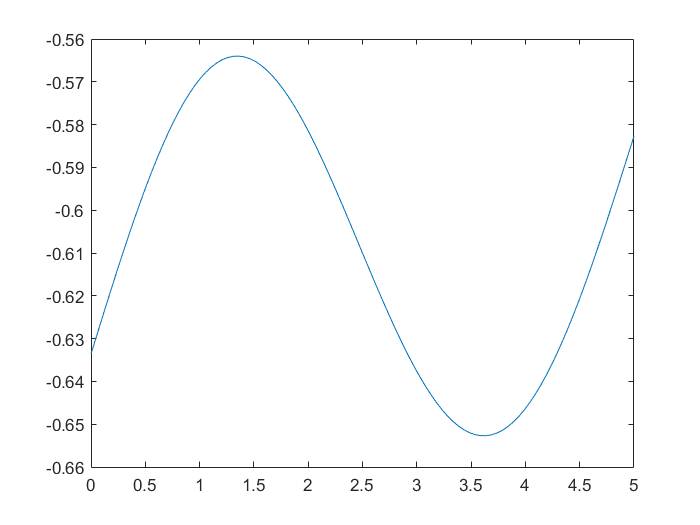

plot(T,Fq(1,:,3))

% save traiettoria_test X Ql T Q S